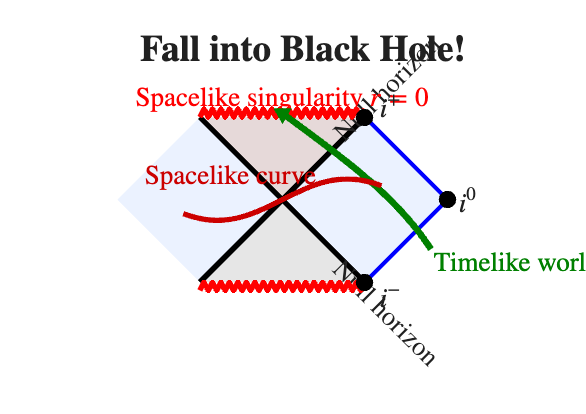

close all; clc;

% LaTeX 解释器与字号
set(0,'DefaultTextInterpreter','latex');
set(0,'DefaultAxesFontSize',14);

% 史瓦西黑洞 
figure('Name','Schwarzschild Causality Flat','Color','w','Position',[100 100 850 600]);
hold on; axis equal; axis off;
xlim([-2.5 3.0]); ylim([-1.5 1.5]);

% 区域颜色
col_I   = [0.92 0.95 1.0]; % 外部区域 
col_II  = [0.9  0.85 0.85]; % 黑洞内部
col_III = [0.9  0.9  0.9];  % 白洞内部 
col_IV  = [0.92 0.95 1.0]; % 平行宇宙 

% 绘制区域
fill([0 1 2 1],[0 1 0 -1],col_I,'EdgeColor','none');
fill([0 -1 -2 -1],[0 1 0 -1],col_IV,'EdgeColor','none');
fill([0 1 -1],[0 1 1],col_II,'EdgeColor','none');   % 奇点在将来
fill([0 1 -1],[0 -1 -1],col_III,'EdgeColor','none'); % 奇点在过去

% 类光视界
LW = 2;
plot([-1 1],[-1 1],'k-','LineWidth',LW);   % 未来视界 H+
plot([-1 1],[1 -1],'k-','LineWidth',LW);   % 过去视界 H-

text(0.65,0.75,'Null horizon','Rotation',45);
text(0.65,-0.75,'Null horizon','Rotation',-45);

%  零无穷远 
plot([1 2],[1 0],'b-','LineWidth',1.5);
plot([1 2],[-1 0],'b-','LineWidth',1.5);

% 类空奇点 
x_zig1 = linspace(-1, 1, 40);
y_zig1 = 1.05 + 0.05 * (-1).^(1:length(x_zig1)); % 振幅 0.05
plot(x_zig1, y_zig1, 'Color', 'r', 'LineWidth', 2);

% 底部奇点
x_zig2 = linspace(-1, 1, 40);
y_zig2 = -1.05 + 0.05 * (-1).^(1:length(x_zig2));
plot(x_zig2, y_zig2, 'Color', 'r', 'LineWidth', 2);

text(0,1.25,'Spacelike singularity $r=0$','Color','r','HorizontalAlignment','center');

% 类时旅行者 (世界线)
% 这是一个落入黑洞的观察者轨迹
t_x = [1.8 1.2 0.6 0.2 0];
t_y = [-0.6 0.1 0.6 0.9 1.05];
color_traveler = [0 0.5 0];
t_idx = 1:length(t_x);
tf_fine = linspace(1, length(t_x), 200);
x_smooth = spline(t_idx, t_x, tf_fine);
y_smooth = spline(t_idx, t_y, tf_fine);

plot(x_smooth, y_smooth, 'Color', color_traveler, 'LineWidth', 2.5);
% 绘制终点箭头
plot(x_smooth(end), y_smooth(end), 'v', 'MarkerFaceColor', color_traveler, 'MarkerEdgeColor', 'none');
text(x_smooth(1), y_smooth(1)-0.15, 'Timelike worldline', 'Color', color_traveler, 'FontWeight', 'bold');

% 类空切片
x_space = linspace(-1.2,1.2,200);
y_space = 0.25*sin(2*x_space);
plot(x_space,y_space,'Color',[0.8 0 0],'LineWidth',2);
text(-1.7,0.3,'Spacelike curve','Color',[0.8 0 0]);

% 标记无穷远点
plot(2,0,'ko','MarkerFaceColor','k');  % 空间无穷远 i0
plot(1,1,'ko','MarkerFaceColor','k');  % 未来类时无穷远 i+
plot(1,-1,'ko','MarkerFaceColor','k'); % 过去类时无穷远 i-

text(2.1,0,'$i^0$');
text(1.15,1.15,'$i^+$');
text(1.15,-1.15,'$i^-$');

title('\textbf{Fall into Black Hole!}');

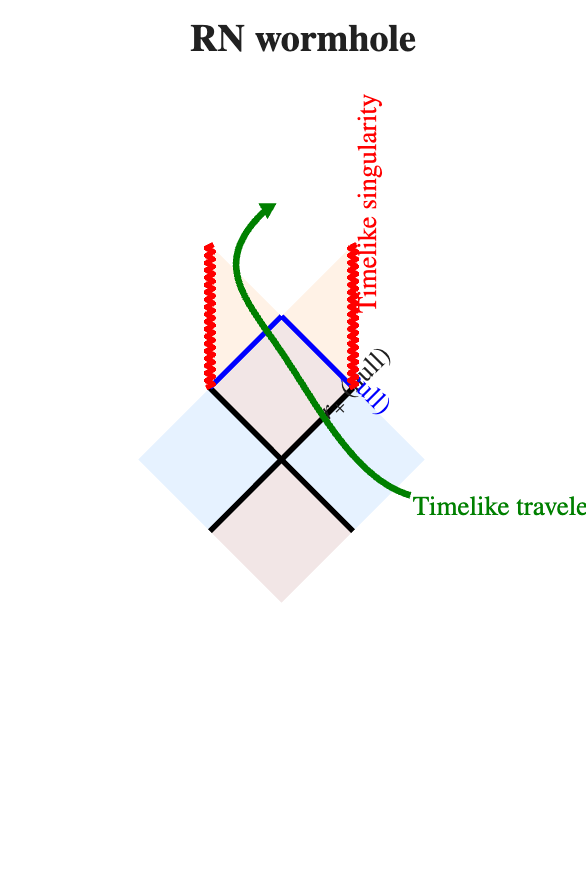


% RN黑洞

figure('Name','RN Causality Flat','Color','w','Position',[950 80 600 900]);
hold on; axis equal; axis off;
axis([-2.2 2.8 -4.5 5.5]);

c_out = [0.9 0.95 1];   % 外部
c_bh  = [0.95 0.9 0.9]; % 外视界内部
c_in  = [1 0.95 0.9];   % 内视界内部

% 中心区域
fill([0 1 0 -1],[0 1 2 1],c_bh,'EdgeColor','none');
fill([0 1 2 1],[0 1 0 -1],c_out,'EdgeColor','none');
fill([0 -1 -2 -1],[0 1 0 -1],c_out,'EdgeColor','none');
fill([0 1 0 -1],[0 -1 -2 -1],c_bh,'EdgeColor','none');

% 类光视界 r+ (外视界) 和 r- (内视界)
plot([0 1],[0 1],'k-','LineWidth',2);
plot([0 -1],[0 1],'k-','LineWidth',2);
plot([0 1],[0 -1],'k-','LineWidth',2);
plot([0 -1],[0 -1],'k-','LineWidth',2);

text(0.55,0.6,'$r_+$ (null)','Rotation',45);
text(0.55,1.6,'$r_-$ (null)','Rotation',-45,'Color','b');

% 延拓区域 (穿越内视界后)
fill([-1 0 -1],[1 2 3],c_in,'EdgeColor','none');
fill([1 0 1],[1 2 3],c_in,'EdgeColor','none');

plot([0 1],[2 1],'b-','LineWidth',2);
plot([0 -1],[2 1],'b-','LineWidth',2);

% 类时奇点 
y_v1 = linspace(1, 3, 40);
x_v1 = -1 + 0.05 * (-1).^(1:length(y_v1)); 
plot(x_v1, y_v1, 'Color', 'r', 'LineWidth', 2);
y_v2 = linspace(1, 3, 40);
x_v2 = 1 + 0.05 * (-1).^(1:length(y_v2)); 
plot(x_v2, y_v2, 'Color', 'r', 'LineWidth', 2);

text(1.2,2,'Timelike singularity','Rotation',90,'Color','r');

% 穿越视界的类时旅行者 
% 观察者穿过 r+ 进入黑洞，再穿过 r- 进入内部宇宙
rn_x = [1.8 0.8 0 -0.6 -0.2];
rn_y = [-0.5 0.3 1.5 2.5 3.5];
color_rn = [0 0.5 0];
t_idx_rn = 1:length(rn_x);
tf_fine_rn = linspace(1, length(rn_x), 200);
x_smooth_rn = spline(t_idx_rn, rn_x, tf_fine_rn);
y_smooth_rn = spline(t_idx_rn, rn_y, tf_fine_rn);

plot(x_smooth_rn, y_smooth_rn, 'Color', color_rn, 'LineWidth', 2.5);
plot(x_smooth_rn(end), y_smooth_rn(end), 'v', 'MarkerFaceColor', color_rn, 'MarkerEdgeColor', 'none');
text(x_smooth_rn(1), y_smooth_rn(1)-0.15, 'Timelike traveler', 'Color', color_rn, 'FontWeight', 'bold');

title('\textbf{RN wormhole}');